# **Passive Microwave Retrieval of Soil Moisture below Snowpack**

**Divya Kumawat and Ardeshir Ebtehaj**

**University of Minnesota**

**October 2022 -- V01**

This live script presents a forward emission model to simulate L-band microwave emission of wet soils below dry snowpack covered with an emerging moderately dense vegetation canopy. The model links the well-known tau-omega emission model with the snowpack dense media radiative transfer theory as well as a multi-layer composite reflection model to account for the impacts of downwelling vegetation emission respectively.

## **1- Emission Model**

As shown in the following schematic, the emission model simulates the suarfce brightness temperatures $$T_b^p$$ at polarization $$p$$ with three main components: (i) upwelling soil emission propagating through the snow layer and attenuated by the vegetation canopy; (ii) upwelling emission by the canopy layer, and (iii) reflected downwelling vegetation emission, transmitted into the intervening snow layer, reflected at the interfaces, and then attenuated by the canopy. 

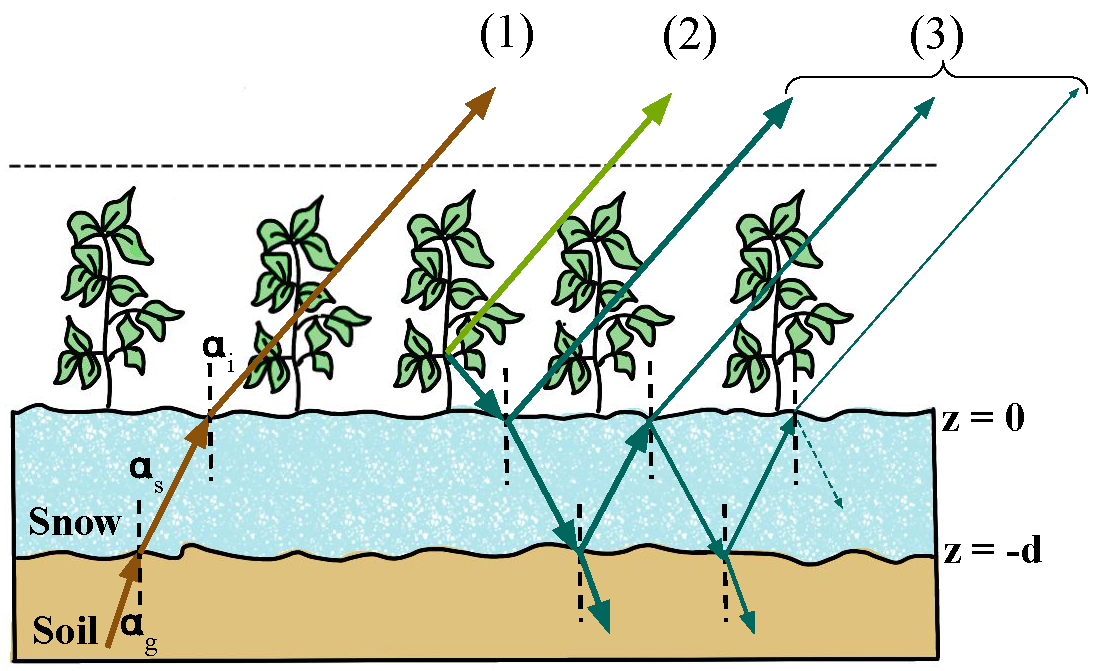

### 
$$$$
T_b^p =T^p_{bs}\gamma+ T_{c}(1-\omega)(1-\gamma)+T_{c}(1-\omega)(1-\gamma)r^p\gamma
$$$$


- (i) Adopted from the well-known zeroth-order $$\tau$-$\omega$$ model [[1]](https://agupubs.onlinelibrary.wiley.com/doi/10.1029/JC087iC13p11229), the upwelling surface emission can be computed as $$T_{bs}^p\gamma$$, where $$T_{bs}^p$$ is the brightness temperature at the snow surface, $$\gamma = \exp(-\tau\sec\alpha_i)$$ is an unpolarized representation of the slanted vegetation transmissivity, $$\tau$$ is the vegetation optical depth (VOD, $$\tau$$), and $$\alpha_i$$ is the incident angle at the canopy-snow boundary. The brightness temperature $$T_{bs}^p$$ can be obtained by linking a dielectric model of wet soil with a snowpack emission model. We adopt the soil dielectric model in [[2]](https://ieeexplore.ieee.org/abstract/document/1288372) and DMRT-QCA model of snowpack emission [[3]](https://ieeexplore.ieee.org/abstract/document/7770720) to compute $$T_{bs}^p$$ -- largely as a function of ground effective temperature $$T_{g}$$, a soil surface roughness parameter $$h$$, volumetric soil moisture (SM, $$\theta$$), soil clay fraction, and snow density $$\rho_{s}$$. 

- (ii) The upwelling vegetation emission is $$T_c(1-\omega)(1-\gamma)$$, where $$T_c$$ is the canopy temperature, and $$\omega$$ denotes an unpolarized representation of the vegetation single scattering albedo. 

- (iii) The contribution to the upwelling brightness temperature arising due to reflection of the downwelling vegetation emission is accounted for as $$T_{c}(1-\omega)(1-\gamma)r^p\gamma$$ in which $$r^p$$ is the effective surface reflectivity of the soil-snow layer composite at polarization $$p$$.

## **2- Forward Simulations**

In the following set of code we simulate L-band brightness temperatures for soil-snow-vegetation system for nadir observation angle of $$40^\circ$$ at horizontal (H-pol) and vertical (V-pol) polarization given $$\rho_s =  100$ and $400$ $\rm{kg.m^{-3}}$$, $$\tau = 0, 0.25$ and $0.5$$ using the above proposed radiaitve trasfer model.

% Add path to local directories 
% This cell shall be run first
clc
clear
addpath('./Data');
addpath('./DMRT');
addpath('./Emission_model');
addpath('./Visualization_functions/')
addpath('./Visualization_functions/parfor_wait')

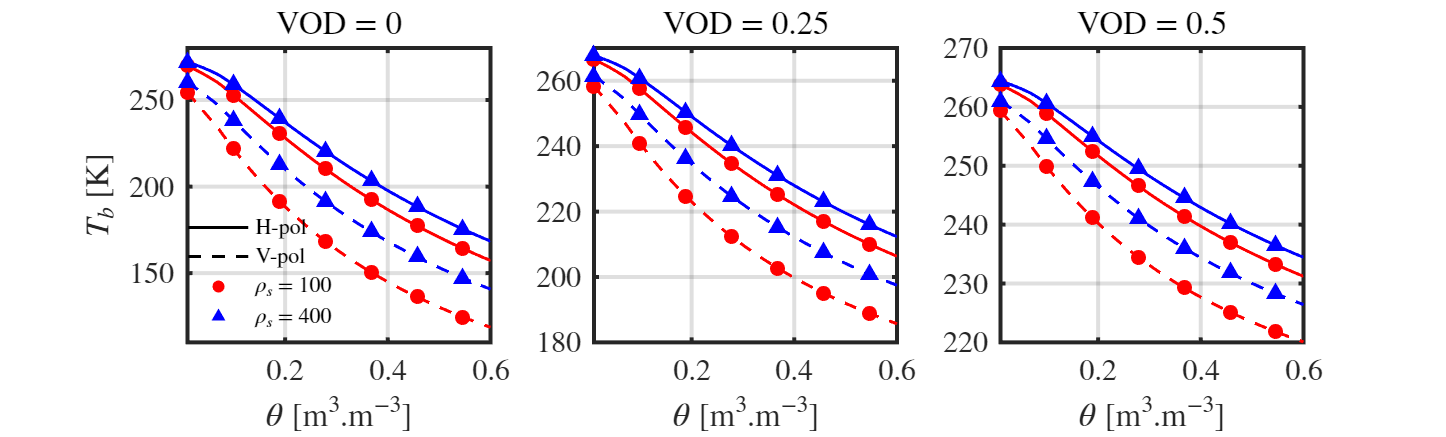

clc
clear
% Inputs
%----------------------------------------------------------------------
omega = 0.05;                       % grasslands
alpha_i = 40;                       % observation incident angle
fGHz = 1.4;                         % frequency
T_g = 275;                          % Temperature of ground
T_snow = 268.15;                    % Mean Temperature of snowpack
T_canopy = 268.15;                  % Temperature of vegetation
clayfrac = 0.13;                    % clay fraction
h = 0.1;                            % roughness parameter (Q/H model)

tau = [0,0.25,0.5];                 % Vegetation Optical depth (VOD)
rho_s = [100,400];                  % Density of snowpack
theta = linspace(0.01,0.6,100);     % Liquid soil moisture content

% Emission model simulations
%----------------------------------------------------------------------
tb_h = nan(length(theta),length(tau),length(rho_s));
tb_v = nan(length(theta),length(tau),length(rho_s));
for i = 1:length(tau)
    for j = 1:length(rho_s)
        for k = 1:length(theta)
            Tb= Emission_model(T_canopy,tau(i),omega,h,fGHz,alpha_i,T_snow,T_g,theta(k),clayfrac,rho_s(j));
            tb_v(k,i,j) = Tb(1);
            tb_h(k,i,j) = Tb(2);
        end
    end
end

% Plotting the simulations
Visualize_forward_EM_model(theta,tb_v,tb_h)

## 3- Synthetic Retrievals under Controlled Erorr

The retrieval scheme searches for the minimum of the weighted sum of squared differences between the observed $\mathbf{y}_{T_b}^p$ and simulated $$T_b^p = f^p(\phi)$$ brightness temperatures while the solutions are constrained between minimum and maximum values of the unknowns as follows [[4]](https://www.sciencedirect.com/science/article/pii/S0034425719303657):


$$$$
\phi^{*}= \underset{\phi}{\text{argmin}\,}{\sum_p  \left[\mathbf{y}_{T_b}^p -f^p( \phi)\right]^2}\,\, \,\,\,\,\,\,\text{subject to} \quad \phi_l \leq \phi \leq \phi_u, 
$$$$


where $$\phi$ =$\left(\theta,\,\tau\right)$$, $$f^p(.)$ $denotes a functional representation of the emission model at polarization $$p = \{H,V\}$$ with incident angle of $$40^\circ$,$ and $$\phi_l$$ and $$\phi_u$$ encode the lower and upper bounds for the unknown variables.

To demonstrate quantitatively the performance of the inversion method, we conduct a series of Monte Carlo experiments with known observation noise. In particular, we produce a large number of forward simulations of brightness temperatures Tb based on the known inputs, corrupt them with a Gaussian observation noise and then report the uncertainties in retrieving SM and VOD. 

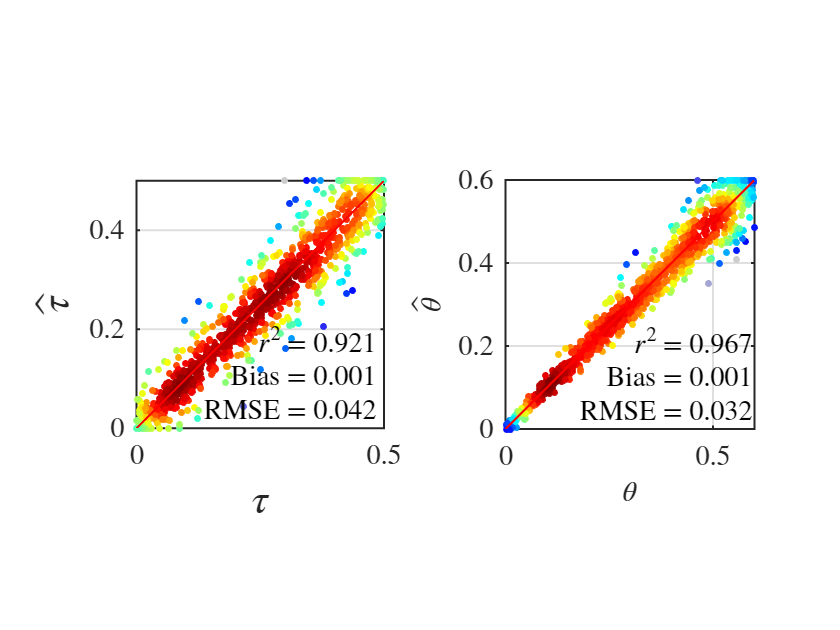

clc
clear
addpath('./Visualization_functions/parfor_wait')

% Inputs
%----------------------------------------------------------------------
omega = 0.05;                       % grasslands
alpha_i = 40;                       % observation angle
fGHz = 1.4;                         % frequency
T_g = 275;                          % Temperature of ground
T_snow = 268.15;                    % Mean Temperature of snowpack
T_canopy = 268.15;                  % Temperature of vegetation
clayfrac = 0.13;                    % clay fraction
h = 0.1;                            % roughness parameter (Q/H model)
N=1000;                             % Number of random samples

tau = unifrnd(0,0.5,1,N);           % Generate random samples from uniform distribution
rho_s= unifrnd(100,400,1,N);        % Generate random samples from uniform distribution
theta = unifrnd(0,0.6,1,N);         % Generate random samples from uniform distribution

combo = [tau',theta',rho_s'];
Tb_obs = zeros(N,2);
for i=1:N
    Tb_obs(i,:)=Emission_model(T_canopy,tau(i),omega,h,fGHz,alpha_i,T_snow,T_g,theta(i),clayfrac,rho_s(i))';
end

sigma_obs_noise=1;                  % Sigma for observation noise [K]

Tb_obs_noise=Tb_obs+normrnd(0,sigma_obs_noise,N,2); % Observed brightness temperature after adding noise

x0 = [0.25 0.3];                    % Initial value
lb = [0 0];                         % Lower Bound
ub = [0.5 0.6];                     % Upper Bound   

Forward_EM = @(T,rho) Emission_model(T_canopy,T(1),omega,h,...
    fGHz,alpha_i,T_snow,T_g,T(2),clayfrac,rho);

options = optimoptions(@lsqnonlin,'Algorithm','trust-region-reflective','display','off','UseParallel',false); % options for Optimization Solver

xopt = zeros(N,2);
WaitMessage = parfor_wait(N, 'Waitbar', true);
parfor i=1:N
    rho = combo(i,3);
    fun = @(T) (Forward_EM(T,rho)-transpose(Tb_obs_noise(i,:)));
    xopt(i,:)=lsqnonlin(fun,x0,lb,ub,options);
    WaitMessage.Send;
    pause(0.002);
end
WaitMessage.Destroy
% Plotting the retrievals
%-----------------------------------------------------------------------------------
Scatter_plot(combo,xopt)

## 4- SMAP Satellite Orbit Retrievals

We implement and evaluate the inversion of the proposed emission model for a SMAP orbital observation over the United States. We use the SMAP overpass on January, 23, 2017 at 9-km resolution.

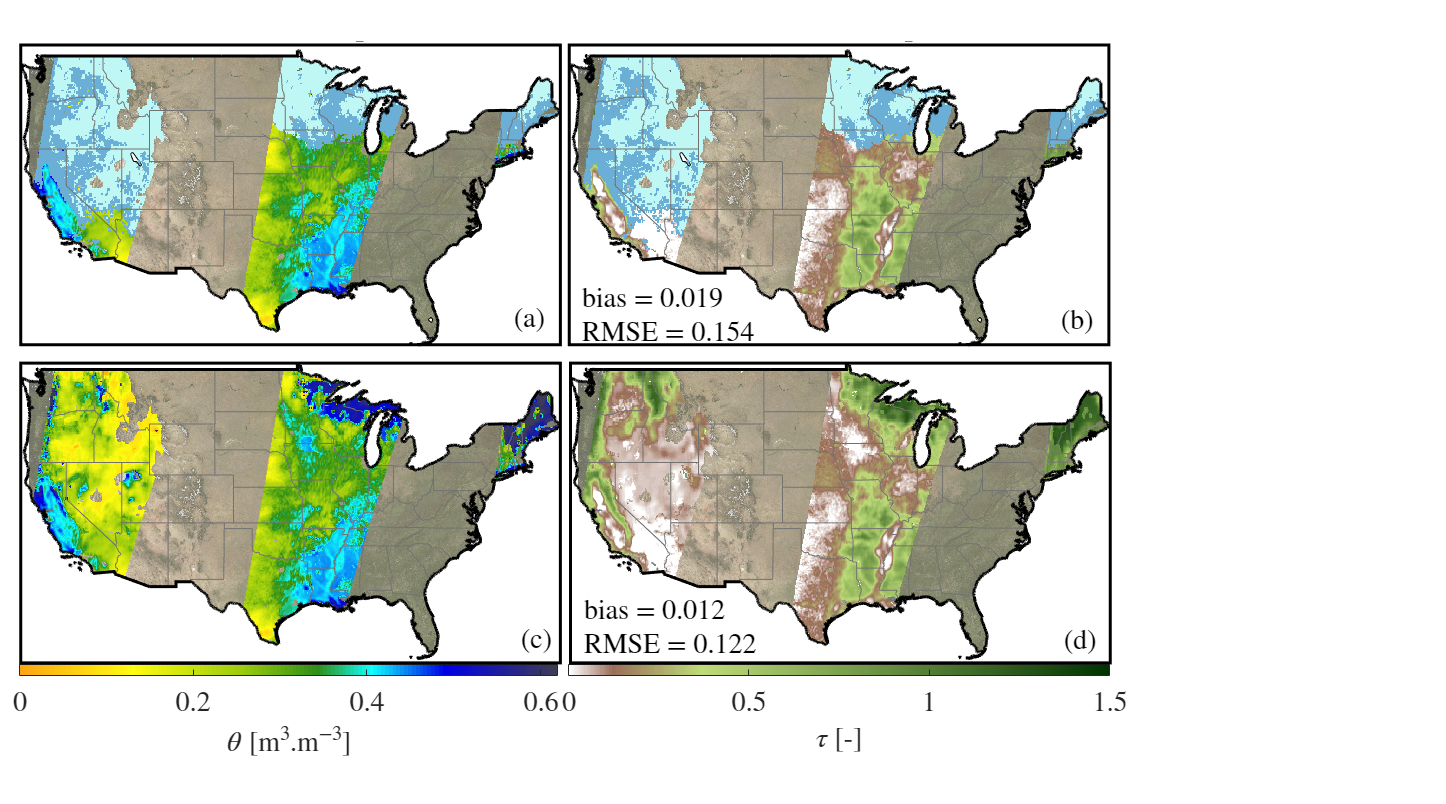

clear
clc
load('Data.mat')
addpath('./Visualization_functions/parfor_wait')

% Inputs
freq = 1.41;     
alpha_i = 40;

% Selecting the retrievable pixels
[ind1, ind2] = find(mask_unfrozensoil_with_snow);
idx = [ind1 ind2];
idx_fun = @(X,idx,i) X(idx(i,1),idx(i,2));

for i=1:length(idx)
    Tb_obs(i,1) = idx_fun(Data.SMAP.tb_v_cor,idx,i);
    Tb_obs(i,2) = idx_fun(Data.SMAP.tb_h_cor,idx,i);
    rho_s(i) = idx_fun(Data.SNODAS.density,idx,i);
    T_snow(i) = idx_fun(Data.SNODAS.snowtemp,idx,i);
    T_g(i) = idx_fun(Data.SMAP.surf_temp,idx,i);
    bulk_density(i) = idx_fun(Data.SMAP.bulk_density,idx,i);
    h_rough(i) = idx_fun(Data.SMAP.roug_coef,idx,i);
    omega_veg(i) = idx_fun(Data.SMAP.albedo,idx,i);
    VOD_ub(i) = idx_fun(Data.VOD_bounds.VOD_max,idx,i);
    VOD_lb(i) = idx_fun(Data.VOD_bounds.VOD_min,idx,i);
    clayfrac(i) = idx_fun(Data.SMAP.clay_frac,idx,i);
end

Forward_EM = @(T,Tsnow,Tg,rho,h,omega,clayfrac) ...
    Emission_model(Tsnow,T(1),omega,h,freq,alpha_i,Tsnow,Tg,T(2),clayfrac,rho);

k=length(Tb_obs);
options = optimoptions(@lsqnonlin,'Algorithm','trust-region-reflective','display','off','UseParallel',false);
% The following for loop needs parallel computing toolbox. 
% Using 6 number of cores with 3.40 GHz clock speed, this cell of code takes 60 minutes.
WaitMessage = parfor_wait(k, 'Waitbar', true);
parfor i=1:k
    Forward_EM2 = @(T) Forward_EM(T,double(T_snow(i)),double(T_g(i)),...
        double(rho_s(i))*1000,double(h_rough(i)),double(omega_veg(i)),double(clayfrac(i)));
    fun = @(T) (double(Forward_EM2(T))-transpose(double(Tb_obs(i,:))));
    x0 = [0.5 0.3];
    lb = [VOD_lb(i) 0.02];
    ub = [VOD_ub(i) double(1-(bulk_density(i)/2.65))];
    xopt(i,:) = lsqnonlin(fun,x0,lb,ub,options);
    WaitMessage.Send;
    pause(0.002);
end
WaitMessage.Destroy
Soil_moist_retrieved = Data.SMAP.soil_moist_dca;
Soil_moist_retrieved(sub2ind(size(Data.SMAP.soil_moist),ind1,ind2))=xopt(:,2);
Tau_retrieved = Data.SMAP.tau_dca;
Tau_retrieved(sub2ind(size(Data.SMAP.tau),ind1,ind2))=xopt(:,1);
SMAP_final_retrieved.sm_r = Soil_moist_retrieved;
SMAP_final_retrieved.tau_r = Tau_retrieved; 
save('./Data/Retrieved_data.mat','SMAP_final_retrieved')

% Visualization of the SMAP orbital retrievals
load('Retrieved_data.mat')
Visualize_orbital_retrieval(Data,SMAP_final_retrieved,...
    mask_snowcover_moistsoil,mask_wet_snow_retrievable_area)